# Group Project (Blue Team)

## Problem 1

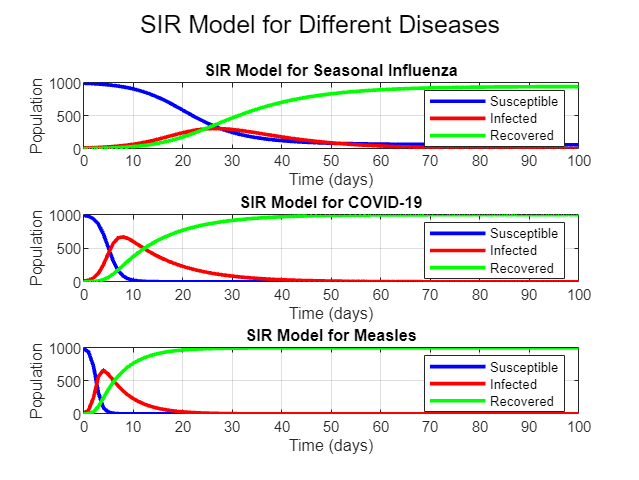


% This live script simulates the dynamics of the Susceptible-Infected-Recovered (SIR) model
% for three different diseases (Seasonal Influenza, COVID-19, and Measles).
% The simulation is run using the 4th-order Runge-Kutta method.



% Simulate and Plot for Different Diseases
% The following code runs the simulation and generates plots for three diseases:



clear;
clc;
T = 100;  % Total simulation time (days)
h = 1;    % Time step (1 day)
h_coarse = 2;    % Coarse time step (2 days)

beta = 0.3;  % Seasonal Influenza parameters
gamma = 0.1;

diseases = {
    'Seasonal Influenza', 0.3, 0.1; % - Seasonal Influenza: b = 0.3, y = 0.1
    'COVID-19', 1.0, 0.1; % - COVID-19: b = 1.0, y = 0.1
    'Measles', 2.0, 0.2; % - Measles: b = 2.0, y = 0.2
};

% Create figure to plot all diseases
figure;
for i = 1:size(diseases, 1)
    disease_name = diseases{i, 1};
    beta = diseases{i, 2};
    gamma = diseases{i, 3};
    
    %SIR model with fine time step (h = 1)
    [t_fine, S_vals_fine, I_vals_fine, R_vals_fine] = simulate_SIR(beta, gamma, T, h);
    
    % Create plots 
    subplot(3, 1, i);
    plot(t_fine, S_vals_fine, 'b', 'LineWidth', 2); hold on;
    plot(t_fine, I_vals_fine, 'r', 'LineWidth', 2);
    plot(t_fine, R_vals_fine, 'g', 'LineWidth', 2);
    
    xlabel('Time (days)');
    ylabel('Population');
    title(['SIR Model for ' disease_name]);
    legend('Susceptible', 'Infected', 'Recovered');
    grid on;
end

% Adjust title of group of plots
sgtitle('SIR Model for Different Diseases');


% Run the coarse simulation (h = 2)
[t_coarse, S_vals_coarse, I_vals_coarse, R_vals_coarse] = simulate_SIR(beta, gamma, T, h_coarse);

% Generate odd days for interpolation 
odd_days = 1:2:T;  % Odd days from 1 to T

% linear nterpolation for coarse time steps 
S_int_linear = linear_interpolation(odd_days, t_coarse, S_vals_coarse);
I_int_linear = linear_interpolation(odd_days, t_coarse, I_vals_coarse);
R_int_linear = linear_interpolation(odd_days, t_coarse, R_vals_coarse);

% quadratic interpolation for coarse time steps
S_int_quadratic = quadratic_interpolation(odd_days, t_coarse, S_vals_coarse);
I_int_quadratic = quadratic_interpolation(odd_days, t_coarse, I_vals_coarse);
R_int_quadratic = quadratic_interpolation(odd_days, t_coarse, R_vals_coarse);

% equivalent fine values for the odd days
S_model_fine_odd = interp1(t_fine, S_vals_fine, odd_days, 'linear');
I_model_fine_odd = interp1(t_fine, I_vals_fine, odd_days, 'linear');
R_model_fine_odd = interp1(t_fine, R_vals_fine, odd_days, 'linear');

% L2 errors for linear interpolation
Nint = length(odd_days); % Number of interpolated points
L2_S_linear = sqrt(sum((S_int_linear - S_model_fine_odd).^2) / Nint);
L2_I_linear = sqrt(sum((I_int_linear - I_model_fine_odd).^2) / Nint);
L2_R_linear = sqrt(sum((R_int_linear - R_model_fine_odd).^2) / Nint);

% L2 errors for quadratic interpolation
L2_S_quadratic = sqrt(sum((S_int_quadratic - S_model_fine_odd).^2) / Nint);
L2_I_quadratic = sqrt(sum((I_int_quadratic - I_model_fine_odd).^2) / Nint);
L2_R_quadratic = sqrt(sum((R_int_quadratic - R_model_fine_odd).^2) / Nint);

% L2 error table
L2_errors = [
    L2_S_linear, L2_I_linear, L2_R_linear;
    L2_S_quadratic, L2_I_quadratic, L2_R_quadratic
];
disp('L2 Error Table:');

L2 Error Table:


disp(array2table(L2_errors, 'VariableNames', {'S(t)', 'I(t)', 'R(t)'}, 'RowNames', {'Linear', 'Quadratic'}));

                  S(t)      I(t)      R(t) 
                 ______    ______    ______

    Linear       23.405    22.215    6.6055
    Quadratic    26.432    25.222    6.0313




% Function to compute the derivatives of the SIR model

function [dS, dI, dR] = sir_derivatives(S, I, R, beta, gamma, N)
    dS = -beta * S * I / N;
    dI = beta * S * I / N - gamma * I;
    dR = gamma * I;
end

% Rk 4 method 
function [S_new, I_new, R_new] = rk4_step(S, I, R, beta, gamma, N, h)
    % Compute the four k's
    [k1_S, k1_I, k1_R] = sir_derivatives(S, I, R, beta, gamma, N);
    [k2_S, k2_I, k2_R] = sir_derivatives(S + 0.5 * h * k1_S, I + 0.5 * h * k1_I, R + 0.5 * h * k1_R, beta, gamma, N);
    [k3_S, k3_I, k3_R] = sir_derivatives(S + 0.5 * h * k2_S, I + 0.5 * h * k2_I, R + 0.5 * h * k2_R, beta, gamma, N);
    [k4_S, k4_I, k4_R] = sir_derivatives(S + h * k3_S, I + h * k3_I, R + h * k3_R, beta, gamma, N);
    
    % Update S, I, R
    S_new = S + (h / 6) * (k1_S + 2 * k2_S + 2 * k3_S + k4_S);
    I_new = I + (h / 6) * (k1_I + 2 * k2_I + 2 * k3_I + k4_I);
    R_new = R + (h / 6) * (k1_R + 2 * k2_R + 2 * k3_R + k4_R);
end

% Function to simulate the SIR model for given parameters
function [t, S_vals, I_vals, R_vals] = simulate_SIR(beta, gamma, T, h)
    N = 1000;  % Total population
    S0 = 990;  % Initial susceptible
    I0 = 10;   % Initial infected
    R0 = 0;    % Initial recovered
    
    % Create time vector
    t = 0:h:T;
    
    % Initial conditions
    S = S0;
    I = I0;
    R = R0;
    
    % Allocate arrays
    S_vals = zeros(size(t));
    I_vals = zeros(size(t));
    R_vals = zeros(size(t));
    
    % Store initial values in array
    S_vals(1) = S;
    I_vals(1) = I;
    R_vals(1) = R;
    
    % RK4 loop
    for i = 2:length(t)
        [S, I, R] = rk4_step(S, I, R, beta, gamma, N, h);
        S_vals(i) = S;
        I_vals(i) = I;
        R_vals(i) = R;
    end
end

% Linear Interpolation Function
function V_int = linear_interpolation(t, t_vals, V_vals)
    V_int = zeros(size(t));
    for i = 1:length(t)
        for j = 2:length(t_vals)
            if t(i) <= t_vals(j)
                V_int(i) = V_vals(j-1) + (V_vals(j) - V_vals(j-1)) * (t(i) - t_vals(j-1)) / (t_vals(j) - t_vals(j-1));
                break;
            end
        end
    end
end

% Quadratic Interpolationfunction
function V_int = quadratic_interpolation(t, t_vals, V_vals)
    V_int = zeros(size(t));
    for i = 1:length(t)
        for j = 3:length(t_vals)
            if t(i) <= t_vals(j)
                x0 = t_vals(j-2); x1 = t_vals(j-1); x2 = t_vals(j);
                y0 = V_vals(j-2); y1 = V_vals(j-1); y2 = V_vals(j);
                V_int(i) = ( (t(i)-x1)*(t(i)-x2) / ((x0-x1)*(x0-x2)) ) * y0 + ...
                           ( (t(i)-x0)*(t(i)-x2) / ((x1-x0)*(x1-x2)) ) * y1 + ...
                           ( (t(i)-x0)*(t(i)-x1) / ((x2-x0)*(x2-x1)) ) * y2;
                break;
            end
        end
    end
end
